**MEC4047F Assignment 1 - Analytical Solution**

(a) Draw the Free Body Diagram for the sprung components of the washing machine and determine the differential equation of motion. The ”sprung components” include the rotating drum, the shroud which contains the water and the motor which is rigidly coupled to the shroud. Following the approach presented in class where we assume a harmonic steady-state displacement response of the form xp(t) = X1 cos(ωt) + X2 sin(ωt), determine the dynamic magnification ratio and the phase angle. Plot the phase angle as a function of frequency ratio

% Physical parameters

m = 50

m = 50

c = 350

c = 350

k = 25000

k = 25000


m_0 = 6

m_0 = 6

e = 0.225

e = 0.2250


% Derived system values

zeta = c/(2*sqrt(m*k))

zeta = 0.1565

omega_n = sqrt(k/m)

omega_n = 22.3607

omega_d = omega_n*sqrt(1-zeta^2)

omega_d = 22.0851

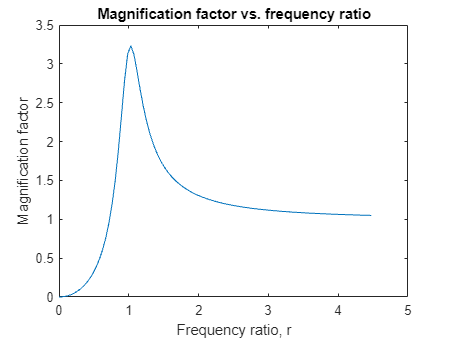


% 

omega = 0:1:100;
r = (omega/omega_n);

mag_fact = (r).^2./sqrt((1-(r).^2).^2 + (2*zeta*r).^2);
phi = atan(2*zeta.*(r)./(1-((r).^2)));

plot(r, mag_fact), title('Magnification factor vs. frequency ratio'), xlabel('Frequency ratio, r'), ylabel('Magnification factor')

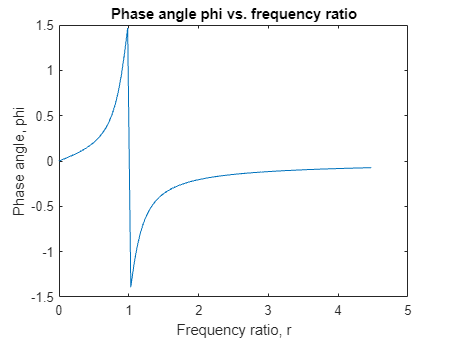

plot(r, phi), title('Phase angle phi vs. frequency ratio'), xlabel('Frequency ratio, r'), ylabel('Phase angle, phi')

(b) Assuming zero initial displacement and velocity, find the analytical solution for the total vertical displacement response (i.e. transient and steady state). Plot the the total displacement response and establish how quickly (in natural periods) the transient dies away, for drum speeds of 400 rpm, 800 rpm and 1200 rpm.

% Solve for transient response

x_0 = ((m + m_0)*9.81)/k

x_0 = 0.0220

x_0_dot = 0

x_0_dot = 0


A_3 = x_0

A_3 = 0.0220

A_4 = (x_0_dot + x_0*zeta*omega_n)/omega_d

A_4 = 0.0035

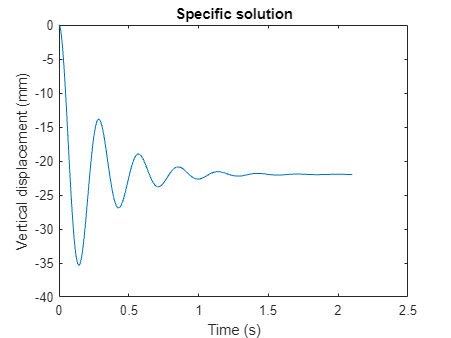


% Plot transient response

x = 0:0.005:2.1;
x_p = (A_3.*cos(omega_d.*x) + A_4.*sin(omega_d.*x)).*exp(-zeta*omega_n.*x) - x_0;

plot(x, x_p*1000), title('Specific solution'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')


% Solve for forced response

omega = [400*0.1047198, 800*0.1047198, 1200*0.1047198]

omega =    41.8879   83.7758  125.6638



f_0 = m_0*e*omega

f_0 =    56.5487  113.0974  169.6461



r = omega/omega_n

r =     1.8733    3.7466    5.6199



phi = atan(2*zeta.*r./(1-(r.^2)))

phi =    -0.2296   -0.0897   -0.0575


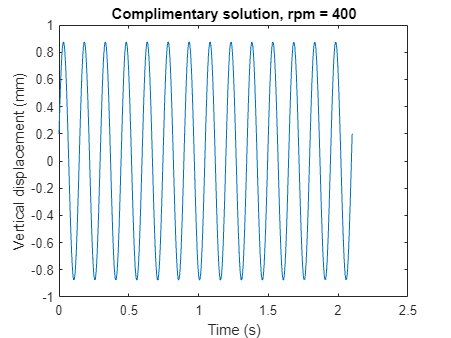


x_c1 = f_0(1)/sqrt((k-m*omega(1)^2)^2 + c^2*omega(1)^2)*sin(omega(1)*x - phi(1));
plot(x, x_c1*1000), title('Complimentary solution, rpm = 400'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')

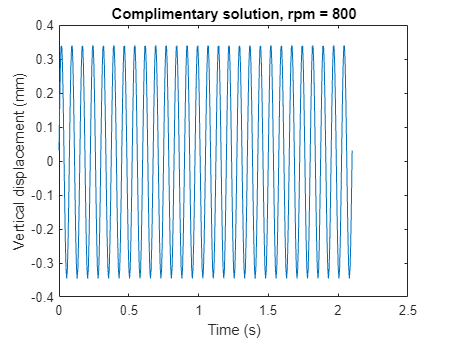


x_c2 = f_0(2)/sqrt((k-m*omega(2)^2)^2 + c^2*omega(2)^2)*sin(omega(2)*x - phi(2));
plot(x, x_c2*1000), title('Complimentary solution, rpm = 800'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')

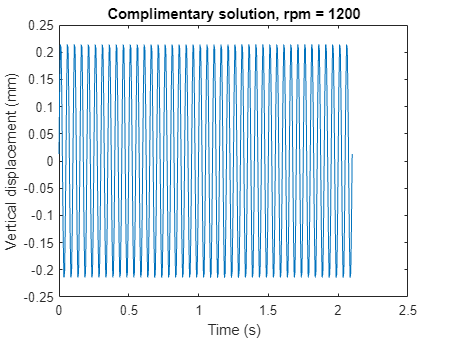


x_c3 = f_0(3)/sqrt((k-m*omega(3)^2)^2 + c^2*omega(3)^2)*sin(omega(3)*x - phi(3));
plot(x, x_c3*1000), title('Complimentary solution, rpm = 1200'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')

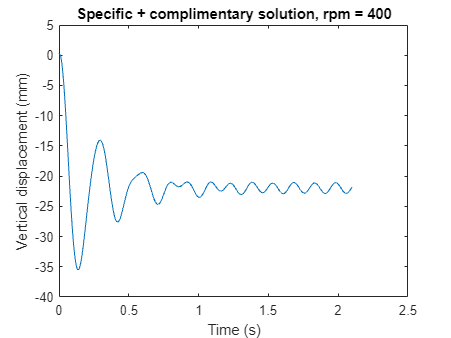


% Plot combined responses

plot(x, (x_p + x_c1)*1000), title('Specific + complimentary solution, rpm = 400'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')

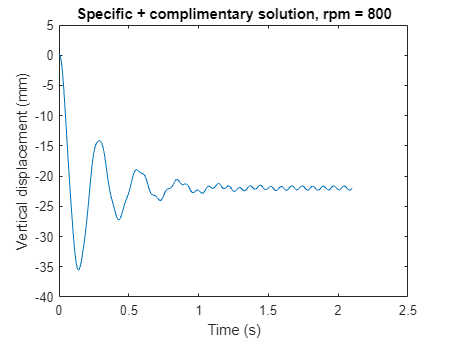

plot(x, (x_p + x_c2)*1000), title('Specific + complimentary solution, rpm = 800'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')

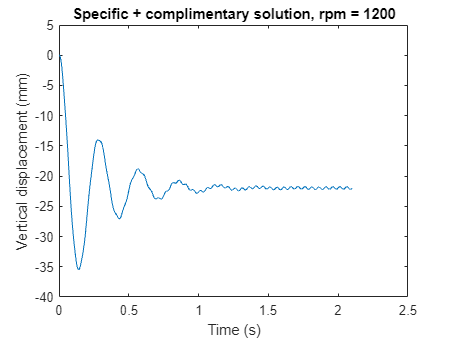

plot(x, (x_p + x_c3)*1000), title('Specific + complimentary solution, rpm = 1200'), xlabel('Time (s)'), ylabel('Vertical displacement (mm)')